imdb = readtable('tfg_codigo/IMDB_Dataset.csv', 'TextType','string');

head(imdb)

                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                  review                                                                                               

numTrain = 40000;
imdb.review = strrep(imdb.review, '<br /><br />', '');
trainData = imdb(1:numTrain, :);
testData = imdb(numTrain:end, :);

review_train = trainData.review;
sentiment_train = trainData.sentiment;
sentiment_test = testData.sentiment;
review_test = testData.review;

review_train = tokenizedDocument(review_train);

% Convert to lowercase.
review_train = lower(review_train);

% Erase punctuation.
documentsTrain = erasePunctuation(review_train);

review_test = tokenizedDocument(review_test);

% Convert to lowercase.
review_test = lower(review_test);

% Erase punctuation.
documentsValidation = erasePunctuation(review_test);


figure
wordcloud(documentsTrain);

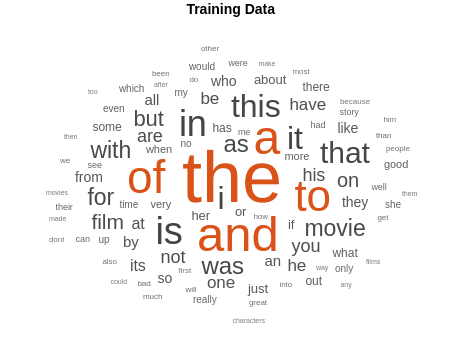

title("Training Data")

enc = wordEncoding(documentsTrain);


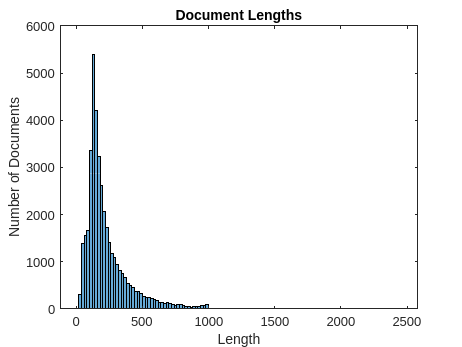

documentLengths = doclength(documentsTrain);
figure
histogram(documentLengths)

xlabel("Longitud")
ylabel("Numero de documentos")

sequenceLength = 500;
XTrain = doc2sequence(end,documentsTrain,'Length',sequenceLength);

The end operator must be used within an array index expression.

XValidation = doc2sequence(enc,documentsValidation,'Length',sequenc ...
    eLength);


layers =   6×1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 1 dimensions
     2   ''   Word Embedding Layer    Word embedding layer with 500 dimensions and 122578 unique words
     3   ''   GRU                     GRU with 80 hidden units
     4   ''   Fully Connected         2 fully connected layer
     5   ''   Softmax                 softmax
     6   ''   Classification Output   crossentropyex